clear all;

## Problem 2

### Part a

Reformulated State Space Model:

m1 = 1;
m2 = 1;
k = 1;

A = [0 0 1 0
        0 0 0 1
      -k/m1 k/m1 0 0
       k/m2 -k/m2 0 0];

B_dist = [ 0    0
      0    0
    1/m1   0
      0  1/m2];

B = [ 0
      0 
    1/m1
      0 ];

C = [ 0 1 0 0];

D = [0 0];

ss_sys = ss(A,B_dist,C,D) %State Space system

ss_sys =
 
  A = 
       x1  x2  x3  x4
   x1   0   0   1   0
   x2   0   0   0   1
   x3  -1   1   0   0
   x4   1  -1   0   0
 
  B = 
       u1  u2
   x1   0   0
   x2   0   0
   x3   1   0
   x4   0   1
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



System Transfer Function:

[num, den] = ss2tf(A,B_dist,C,D,1);

tf_sys = tf(num,den)

tf_sys =
 
                           1
  ----------------------------------------------------
  s^4 - 1.89e-17 s^3 + 2 s^2 - 1.408e-16 s - 3.263e-32
 
Continuous-time transfer function.



### Part b

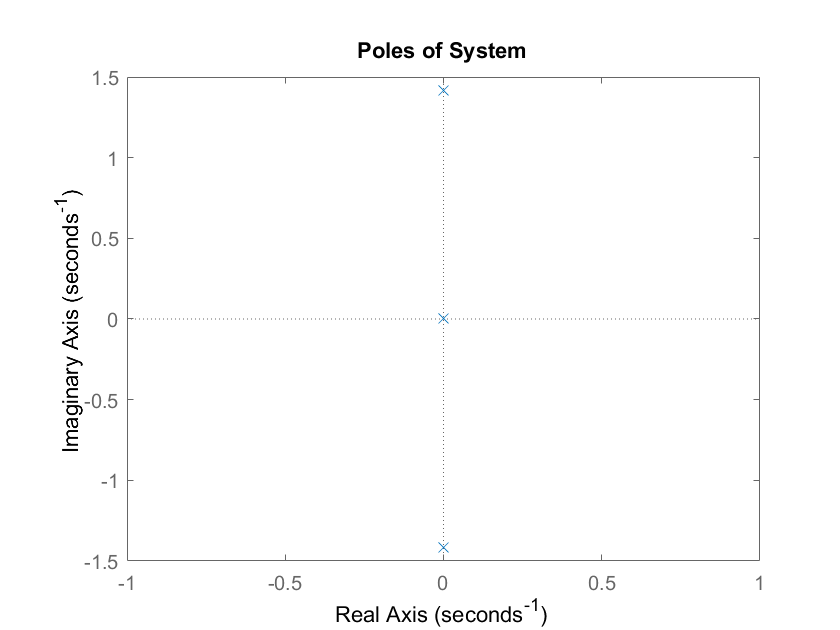

figure 
pzmap(tf_sys)
xlim([-1 1])
title('Poles of System')

### Part c

The dominant pole approximation will be made such that output x2 can be considered a 2nd order system with a damping ratio and natural frequency. These system properties are found from the transients, percent overshoot, and settling time. The resultant poles of the second order system are found and the remaining two poles are placed on the real line at -10 and -11 times the real part of those poles. Then, a full state feedback controller is implemented so that the poles of the single input, single output system can be arbitrarily placed. They are placed at the locations from the dominant pole approximation. 

Choose transient properties:

POS = 10; %10 percent overshoot
ST = 1; %Settling time of 1 second
Tol_frac = 0.02; %Tolerance fraction of 2%
Ts = 1; %Settling time is 1 second

DR = -log(POS/100)/sqrt(pi^2 + log(POS/100)^2) %Damping ratio as function of percent overshoot

DR = 0.5912

Wn = -log(Tol_frac*sqrt(1-DR^2))/(DR*Ts) %Natural frequency from damping ratio and settling time

Wn = 6.9813

Find Poles from $\zeta$ and $\omega_n$

beta = acos(DR)

beta = 0.9383

P1 = -Wn*cos(beta) + 1i*Wn*sin(beta)

P1 = -4.1270 + 5.6308i

P2 = conj(P1);

P3 = real(P1)*10

P3 = -41.2700

P4 = P3*11/10;

K = place(A,B,[P1 P2 P3 P4])

K = 	1.0e+04 *

    0.2636    8.8677    0.0095    1.9593


Full State Feedback Controller - Free Response from $x_0$, with d = 0

%Simulation Setup
d = 0; %Magnitude of the step disturbance

Dis_Vec = [0
           0
           0
           1/m2];

x0 = [1 2 0 0]';

tstop = 3;


Block Diagram for system with optional input disturbance d:

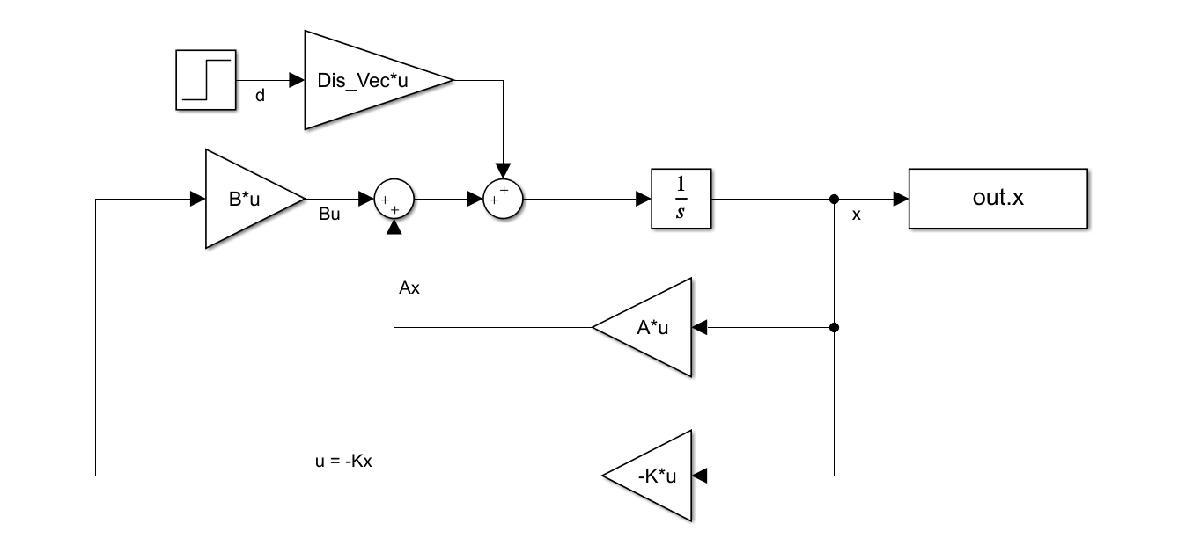

Run Simulink Model for the full state feedback regulation controller

simout = sim('FSF_w_disturbance.slx');

Plot results

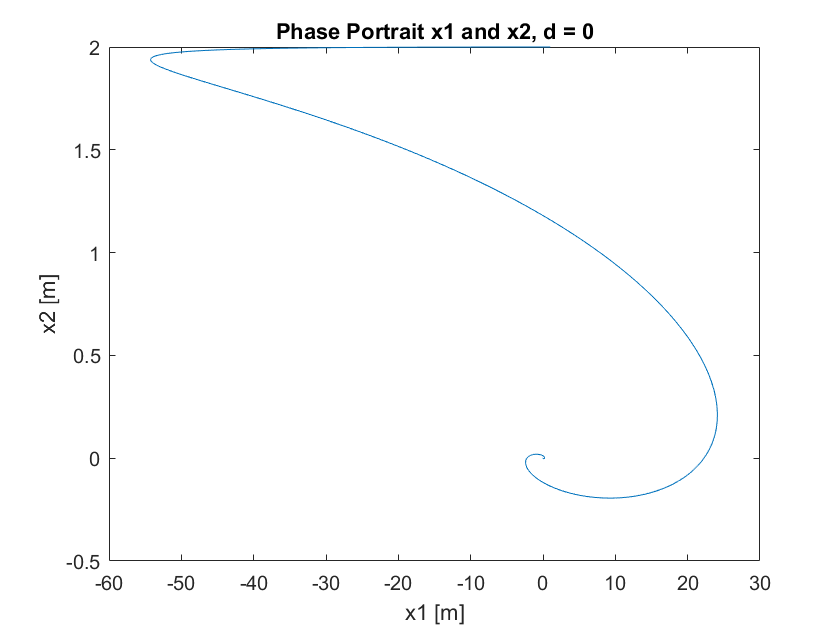

figure
x1 = simout.x(:,1);
x2 = simout.x(:,2);
plot(x1,x2)

xlabel('x1 [m]')
ylabel('x2 [m]')
title('Phase Portrait x1 and x2, d = 0')

### Part d

Full State Feedback Controller - Free Response from $x_0$, with d = 1

%Simulation Setup
d = 1; %Magnitude of the step disturbance

Dis_Vec = [0
           0
           0
           1/m2];

x0 = [1 2 0 0]';

tstop = 3;


Block Diagram for system with optional input disturbance d:

Run Simulink Model for the full state feedback regulation controller

simout = sim('FSF_w_disturbance.slx');

Plot results

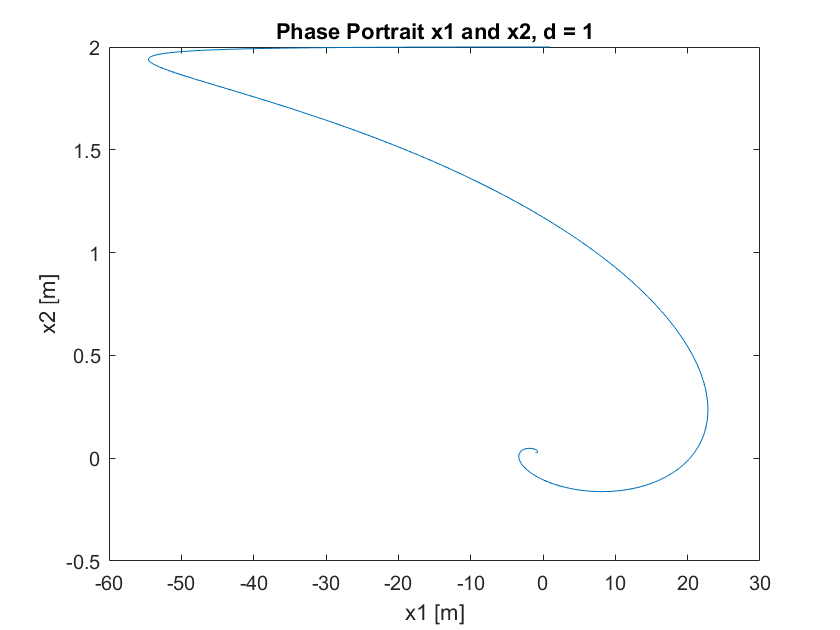

figure
x1 = simout.x(:,1);
x2 = simout.x(:,2);
plot(x1,x2)

xlabel('x1 [m]')
ylabel('x2 [m]')
title('Phase Portrait x1 and x2, d = 1')

The controller appears to have successfully rejected the distrurbance and regulated the states to zero. 

## Problem 3

### Part c

Linearized System

m = 1; %Mass of pendulum [kg]
M = 10; %Mass of cart [kg]
l = 1; %Length of pendulum arm [m]
g = 10; %Gravitational acceleration [m/s^2]

A = [0 1     0          0 
     0 0 -m*g/M         0
     0 0     0          1
     0 0 (M+m)*g/(l*M)  0];

B = [0 1/M 0 -1/(l*M)]';

C = eye(4); %Full state feedback

D = [0 0 0 0]';


Pole Selection:

The poles must be stable, in the left hand plane and have at least some amount of decay - no pure oscillations. One complex conjugate pair and two strictly real roots are chosen. The poles are iterated on manually to find a suitable transient regulation response from a $\theta_0$ of $\pi/10$ and $x_0$ of 0. The transient response was considered suitable if steady state is reached within 3 seconds and $\theta$ never exceeds 0.5radians (about 30 degrees and 4% small-angle approximation error).

The place command is used in the multi-output system where the MATLAB function decides on a single K matrix from a space of viable matrices (K is not unique). 

P1 = -3 + 1i;
P2 =  conj(P1);
P3 = -4;
P4 = -5;

K = place(A,B,[P1 P2 P3 P4])

K = 	1.0e+03 *

   -0.2000   -0.2100   -1.1500   -0.3600


Full State Feedback State Space Model:


$$\dot{x} = (A - BK)x
$$


fsfb_ss = ss(A-B*K,zeros(size(B)), eye(4), D) %Full state feedback state space object

fsfb_ss =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2    20    21   114    36
   x3     0     0     0     1
   x4   -20   -21  -104   -36
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



Run simulation from initial conditions: $\tilde{x} _0 = [x_0 ~\dot{x}_0 ~ \theta_0 ~ \dot{\theta}_0]$

theta_0 = pi/10; %Initial angular displacement
x0 = [0 0 theta_0 0]; %Initial state vector
tf = 3; %Simulation time
[y, t_lin, x_lin] = initial(fsfb_ss ,x0);


Plot linear transient response of $x$ and $\theta$

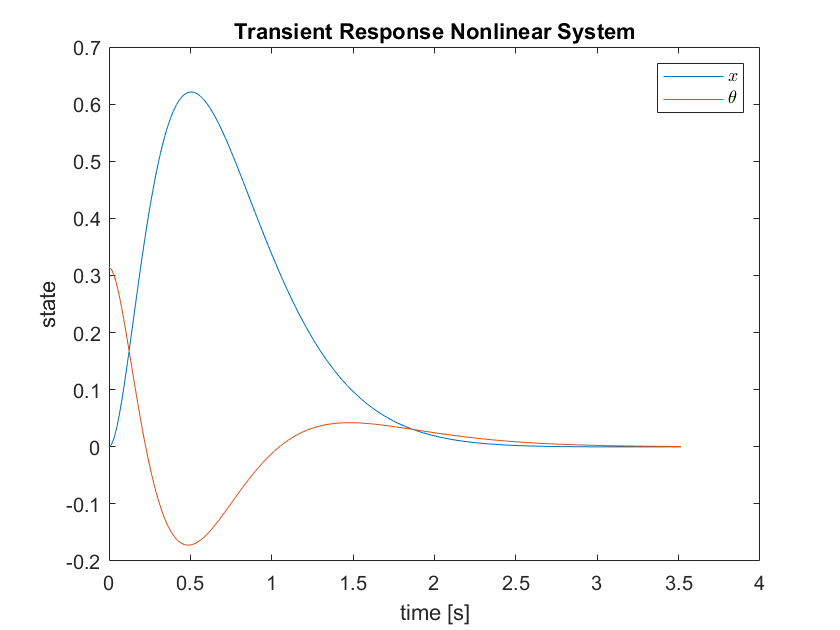

figure
plot(t_lin,x_lin(:,[1,3]))
legend('$x$','$\theta$','interpreter','latex')
xlabel('time [s]')
ylabel('state')
title('Transient Response Nonlinear System')

The transient response shown above was a result of manual iteration on the pole selection. With the chosen poles, the time criteria was met and the system stayed well within the small angle approximation. 

### Part d

Function handle for the pendulum-cart equation of motion (want K to be able to vary with the script but ode45 wants (t,x))

eomHandle = @(t,x)sysEOM_CL(t,x,K); 


#### Theta = pi/10

Run the simulation for the closed loop nonlinear system model

tspan = [0 tf];
[t_nlin,x_nlin] = ode45(eomHandle, tspan, x0);


Plot nonlinear transient response of $x$ and $\theta$

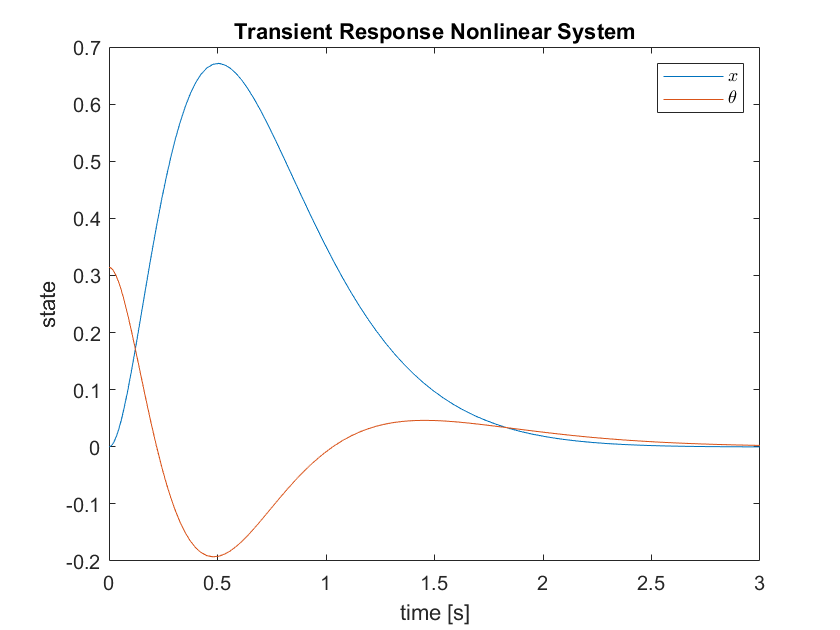

plot(t_nlin,x_nlin(:,[1,3]))
legend('$x$','$\theta$','interpreter','latex')
xlabel('time [s]')
ylabel('state')
title('Transient Response Nonlinear System')

Plot phase portraits in x1,x2 and x3,x4 planes

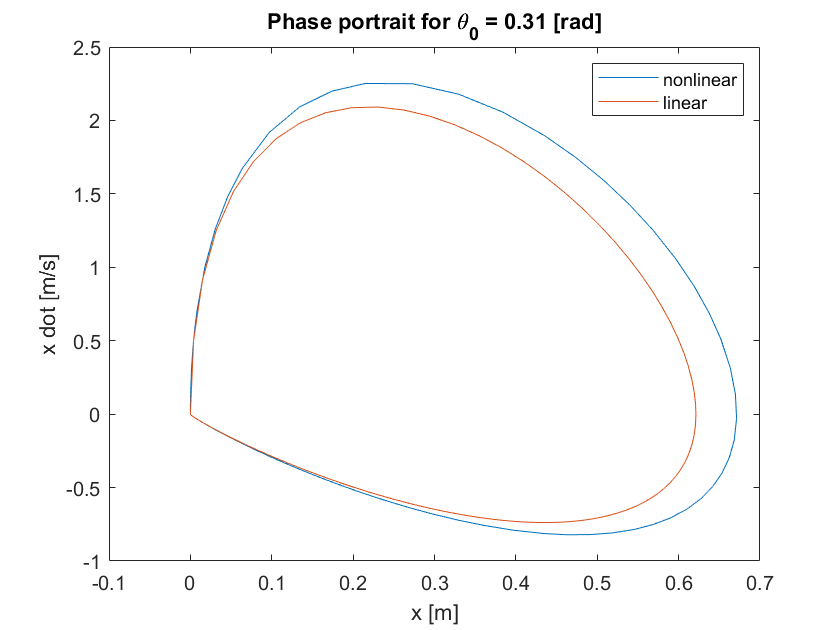

figure
plot(x_nlin(:,1),x_nlin(:,2),x_lin(:,1),x_lin(:,2))
legend('nonlinear', 'linear')
xlabel('x [m]')
ylabel('x dot [m/s]')
title(['Phase portrait for \theta_0 = ', num2str(theta_0,2), ' [rad]']);

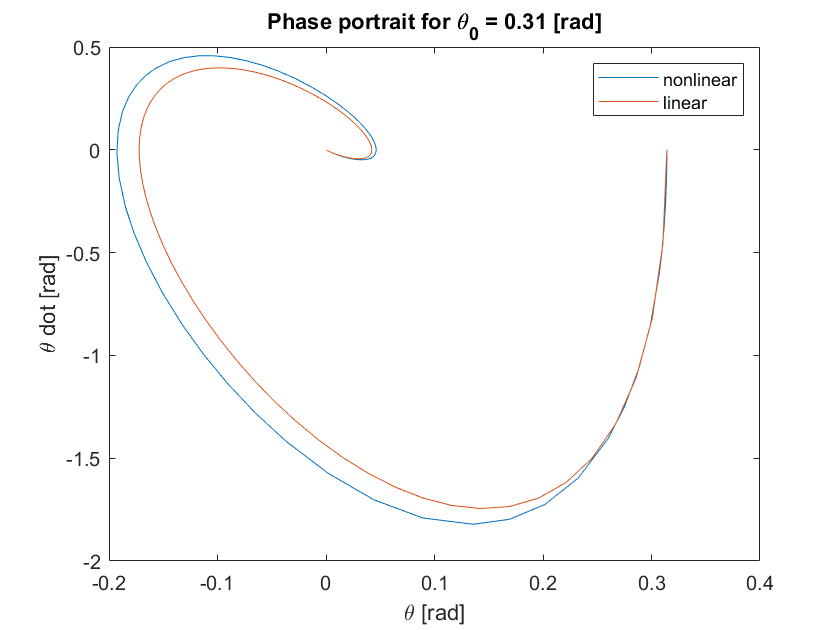


figure
plot(x_nlin(:,3),x_nlin(:,4),x_lin(:,3),x_lin(:,4))
legend('nonlinear', 'linear')
xlabel('\theta [rad]')
ylabel('\theta dot [rad]')
title(['Phase portrait for \theta_0 = ', num2str(theta_0,2), ' [rad]']);

#### Theta = 1.5*pi/10

Run the simulation for the closed loop nonlinear system model

tspan = [0 tf];
theta_0 = 1.5*pi/10; %Initial angular displacement
x0 = [0 0 theta_0 0]; %Initial state vector

opts = odeset('RelTol',1e-3);
[t_nlin,x_nlin] = ode45(eomHandle, tspan, x0, opts);


Plot phase portraits in x1,x2 and x3,x4 planes

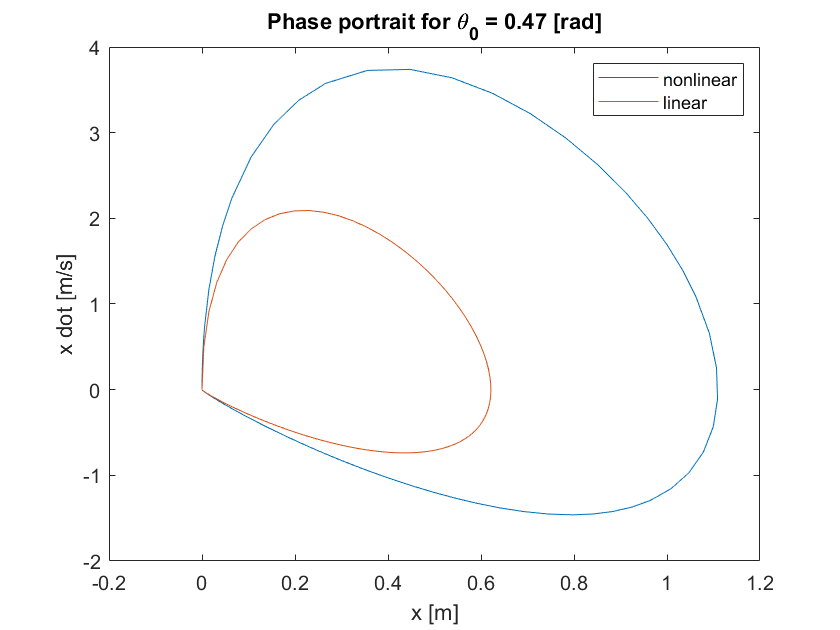

figure
plot(x_nlin(:,1),x_nlin(:,2),x_lin(:,1),x_lin(:,2))
legend('nonlinear', 'linear')
xlabel('x [m]')
ylabel('x dot [m/s]')
title(['Phase portrait for \theta_0 = ', num2str(theta_0,2), ' [rad]']);

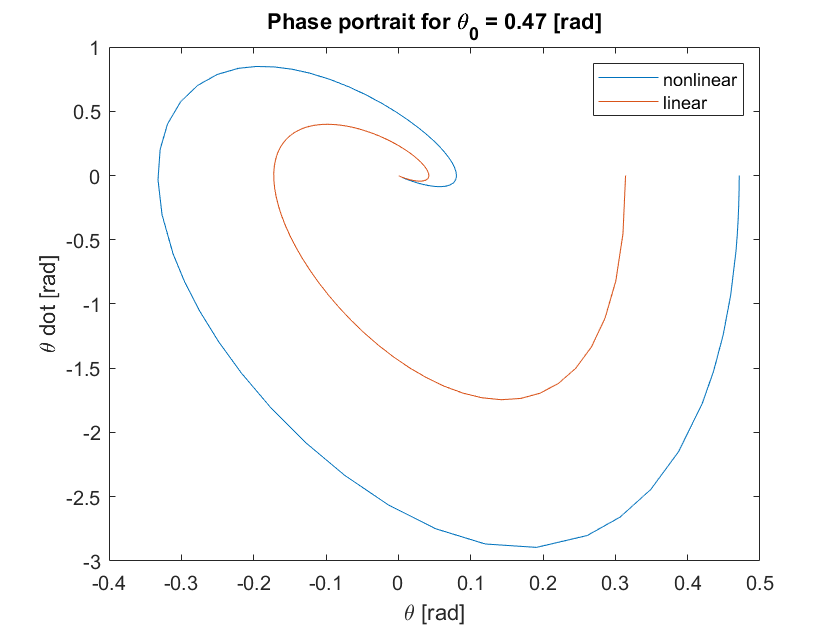


figure
plot(x_nlin(:,3),x_nlin(:,4),x_lin(:,3),x_lin(:,4))
legend('nonlinear', 'linear')
xlabel('\theta [rad]')
ylabel('\theta dot [rad]')
title(['Phase portrait for \theta_0 = ', num2str(theta_0,2), ' [rad]']);

#### Theta = 2*pi/10

Run the simulation for the closed loop nonlinear system model

tspan = [0 tf];
theta_0 = 2*pi/10; %Initial angular displacement
x0 = [0 0 theta_0 0]; %Initial state vector

opts = odeset('RelTol',1e-3);
[t_nlin,x_nlin] = ode45(eomHandle, tspan, x0, opts);


Plot phase portraits in x1,x2 and x3,x4 planes

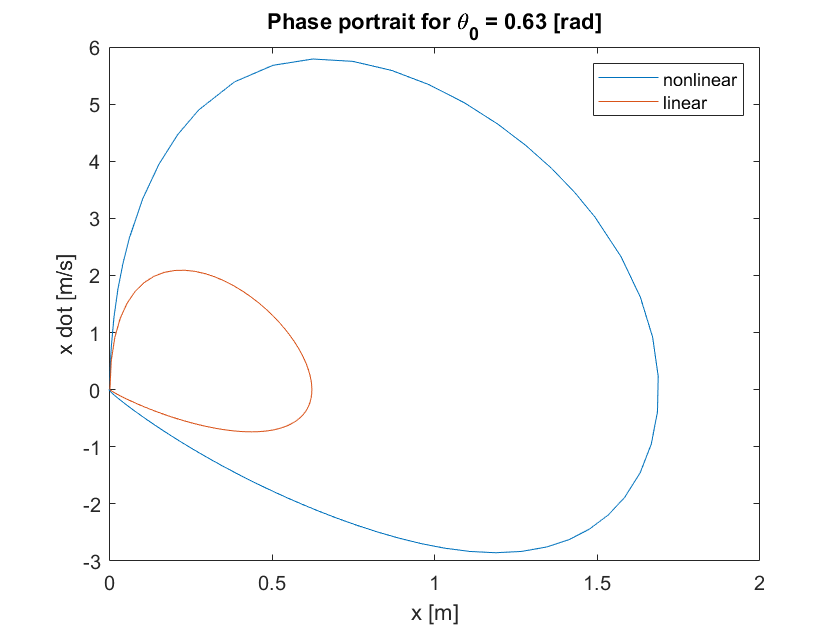

figure
plot(x_nlin(:,1),x_nlin(:,2),x_lin(:,1),x_lin(:,2))
legend('nonlinear', 'linear')
xlabel('x [m]')
ylabel('x dot [m/s]')
title(['Phase portrait for \theta_0 = ', num2str(theta_0,2), ' [rad]']);

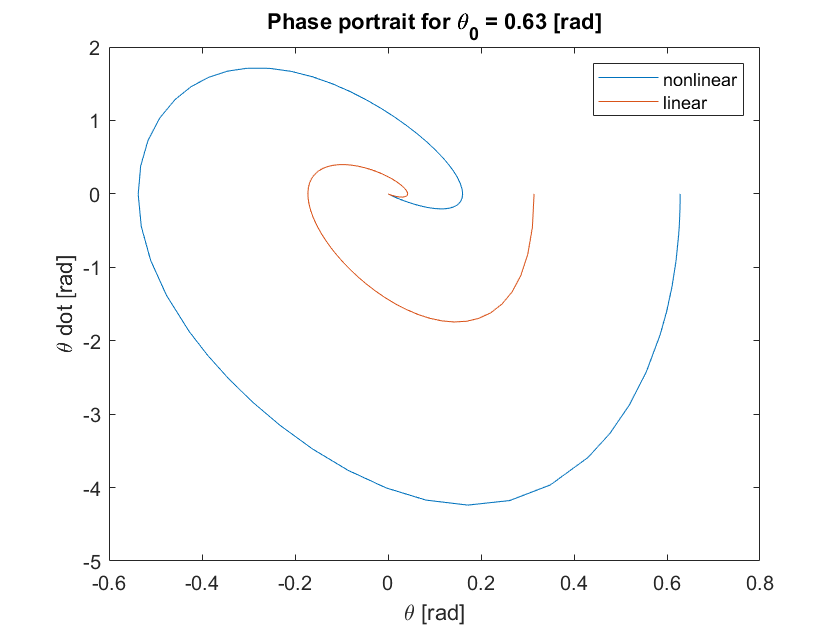


figure
plot(x_nlin(:,3),x_nlin(:,4),x_lin(:,3),x_lin(:,4))
legend('nonlinear', 'linear')
xlabel('\theta [rad]')
ylabel('\theta dot [rad]')
title(['Phase portrait for \theta_0 = ', num2str(theta_0,2), ' [rad]']);

From the above three responses, the trend can be seen clearly - the effectiveness of the linear controller in the nonlinear system model is greatly dependant on the initial angle. The greater the offset from equilibrium, the more poorly the controller performs. At a value of 3*pi/10, the ODE45 at a relative tolerance of e-3 was running for an unreasonable amount of time. This indicates that the nonlinear system went unstable and was not able to regulate the states to zero. There were likely solver issues as a result of this. 

# Functions

Pendulum Nonlinear EOM

function xdot = sysEOM_CL(t,x,K)

    m = 1; %Mass of pendulum [kg]
    M = 10; %Mass of cart [kg]
    l = 1; %Length of pendulum arm [m]
    g = 10; %Gravitational acceleration [m/s^2]

    %x(1) = x
    %x(2) = x_dot
    %x(3) = theta
    %x(4) = theta_dot
    
    u = -K*x;
    
    xdd = (u + m*sin(x(3))*(l*x(4)^2 - g*cos(x(3))))/(M + m*sin(x(3))^2);
    
    thdd = (-u*cos(x(3)) - m*l*x(4)^2*sin(x(3))*cos(x(3)) + (M+m)*g*sin(x(3)))/(l*(M+m*sin(x(3))^2));
    
    xdot = [x(2)
            xdd
            x(4)
            thdd];

end